# Compare Stellar Spectra

This code loads the data from the previous project.

load starData

## Task 1

[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


## Tasks 2 - 4

for c = 1:7
    s = spectra(:,c);

    if speed(c) <= 0
        loglog(lambda,s,"--")
    else
       loglog(lambda,s,LineWidth=3) 
    end
    hold on
end
hold off

## Task 5

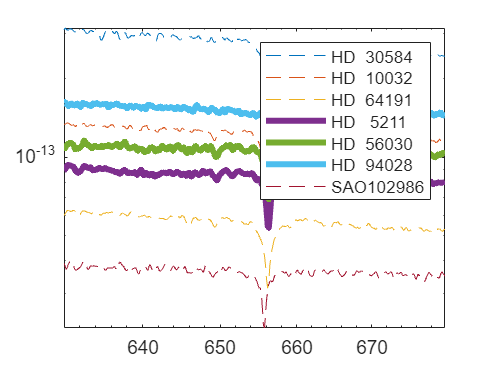

legend(starnames)

## Task 6

movaway = starnames(speed > 0) 

movaway = 3×1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"


## Further Practice